
clear
q0 =0 %%initial position
v0 = 0%%initial velocity
ac0 =0%% initial acceleration
q1 = 5%%final position
v1 = 0%%final velocity
ac1 =0%% final acceleration
t0 = 0%%initial time
tf = 1%%final time




close all
clear


Vi=0

Vi = 0

Vf=12

Vf = 12

t0=0

t0 = 0

tf=5

tf = 5

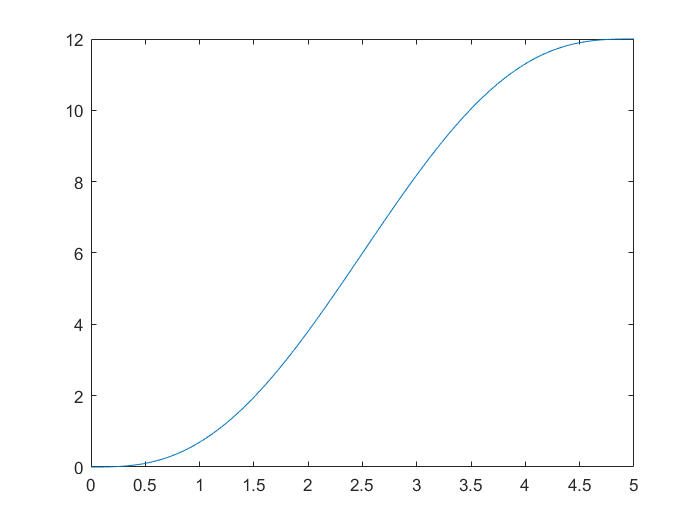



Vd=perfil_voltaje(Vi, 0, 0, Vf, 0, 0, t0, tf,100);


plot(linspace(0,tf,length(Vd)), Vd)

function [qd, vd, ad] = perfil_movimiento(q0, v0, ac0, q1, v1, ac1, t0, tf, npoints)

t = linspace(t0, tf, npoints);
c = ones(size(t));
M = [ 1 t0 t0^2 t0^3 t0^4 t0^5;
      0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
      0 0 2 6*t0 12*t0^2 20*t0^3;
      1 tf tf^2 tf^3 tf^4 tf^5;
      0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
      0 0 2 6*tf 12*tf^2 20*tf^3];

b = [q0; v0; ac0; q1; v1; ac1];
a = M^-1 * b;

qd = a(1).*c + a(2).*t +a(3).*t.^2 + a(4).*t.^3 +a(5).*t.^4 + a(6).*t.^5;
vd = a(2).*c +2*a(3).*t +3*a(4).*t.^2 +4*a(5).*t.^3 +5*a(6).*t.^4;
ad = 2*a(3).*c + 6*a(4).*t +12*a(5).*t.^2 +20*a(6).*t.^3;

end


function qd = perfil_voltaje(q0, v0, ac0, q1, v1, ac1, t0, tf, npoints)

t = linspace(t0, tf, npoints);
c = ones(size(t));
M = [ 1 t0 t0^2 t0^3 t0^4 t0^5;
      0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
      0 0 2 6*t0 12*t0^2 20*t0^3;
      1 tf tf^2 tf^3 tf^4 tf^5;
      0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
      0 0 2 6*tf 12*tf^2 20*tf^3];

b = [q0; v0; ac0; q1; v1; ac1];
a = M^-1 * b;

qd = a(1).*c + a(2).*t +a(3).*t.^2 + a(4).*t.^3 +a(5).*t.^4 + a(6).*t.^5;

end
